# Engineering MATLAB

ODEs and PDEs

clear, clc, close all;

## Introduction to Ordinary Differential Equations (ODEs)

### Mathematical Background

Most applied mathematics is concerned with answering real-life problems, which are modeled with differential equations. Differential equations can be classified into two main groups: Ordinary and Partial. Ordinary differential equations are standard equations of the form


$$\frac{dx}{dt} = f(t,x)$$


where $f(x,t)$ is some function that models the dynamics of the system we are analyzing. For this discussion, we will be limiting ourselves to first order differential equations.

### Important Algorithms

For this example, we will be solving the differential equation 

$\frac{dx}{dt} = -2x$, $x(0) = 3$

The solution to this ODE is 


$$x(t) = 3e^{-2t}$$


#### Euler's Method

Euler's method is the first ODE solver that most students discover in their first semester physics course. The approximation scheme is quite easy: we will use the definition of the derivative to solve for x at each time step.

Notation:

$x_n$ - position at index (or time) $n$.

$x_{n+1}$ - position at index (or time) $n+1$.

$t_n$ - time at index $n$.

Derivation of algorithm:

Starting with the forward difference:


$$\frac{x_{n+1} - x_{n}}{\Delta t} = f(t,x)$$


Our goal is to solve for $x_{n+1}$:


$$x_{n+1} = x_{n} + \Delta t \cdot f(t,x)$$


Making $\Delta t$ small enough, we get our time-step equation for Euler's Method:


$$x_{n+1} = x_n + dt \cdot f(t,x)$$


The algorithm is the following:

euler_method: 

inputs - f (anonymous function), x0 (initial condition), t0 (initial time), tstop ( final time value), dt (timestep)

outputs - x (position), t (time)

- Create vector of time values initial_time : dt : tstop

- Allocate a vector of zeros for x (this is for performance, doesn't have to be done)

- Set x(1) = x0, this is the initial condition.

- Iterate in a loop for the length of vector t:

-     x(n+1) = x(n) + dt*f(t(n), x(n))

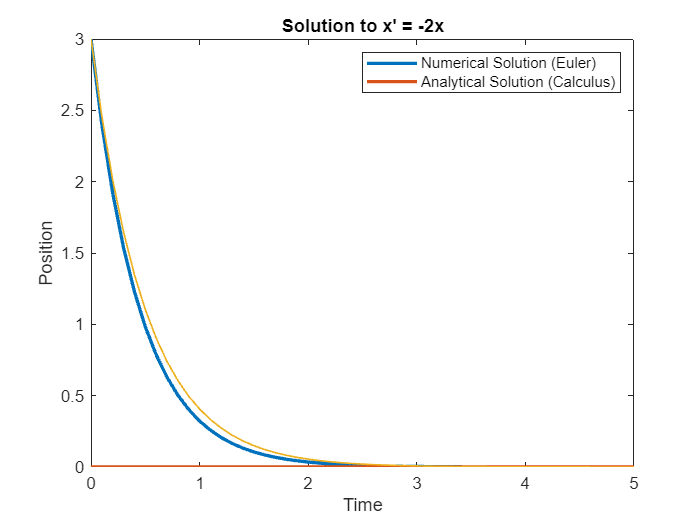

% euler method
function [t, x] = euler_method(f, x0, t0, tstop, dt)

    % f - annonymous function
    % x0 - initial condition
    % t0 - initial time
    % tstop - final time
    % dt - time step (like 0.01 or something)

    t = t0 : dt : tstop;
    x = zeros(length(t));

    x(1) = x0;

    for i = 1:length(t)
            x(i+1) = x(i) + dt * f(t(i), x(i));
    end

end


f = @(t, x) -2 * x;
x0 = 3;
t0 = 0;
tstop = 5;
dt = 0.1;
[t, x] = euler_method(f, x0, t0, tstop, dt);

f_actual = @(t) 3 * exp(-2*t);

figure
plot(t, x, 'LineWidth', 2)
xlabel("Time")
ylabel("Position")
title("Solution to x' = -2x")
hold on;
plot(t, f_actual(t), 'LineWidth', 1)
legend("Numerical Solution (Euler)", "Analytical Solution (Calculus)");
hold off;

#### Runge-Kutta 4

This algorithm is a little more complicated so the derivation will be ignored. This method involves computing four separate slopes and using them in a final approximation:


$$k_1 = f(t_n,x_n)$$



$$k_2 = f\left(t_n + \frac{dt}{2}, x_n + dt \cdot \frac{k_1}{2}\right)$$



$$k_3 = f \left( t_n + \frac{dt}{2}, x_n + dt \cdot \frac{k_2}{2}\right)$$



$$k_4 = f \left(t_n + dt, x_n + dt \cdot k_3 \right)$$


The initial part of the algorithm is the same as Euler's Method we will calculate intermediate slopes before getting our final value:


$$x_{n+1} = x_n + \frac{dt}{6}\cdot \left(k_1 + 2k_2 + 2k_3 + k_4 \right)$$


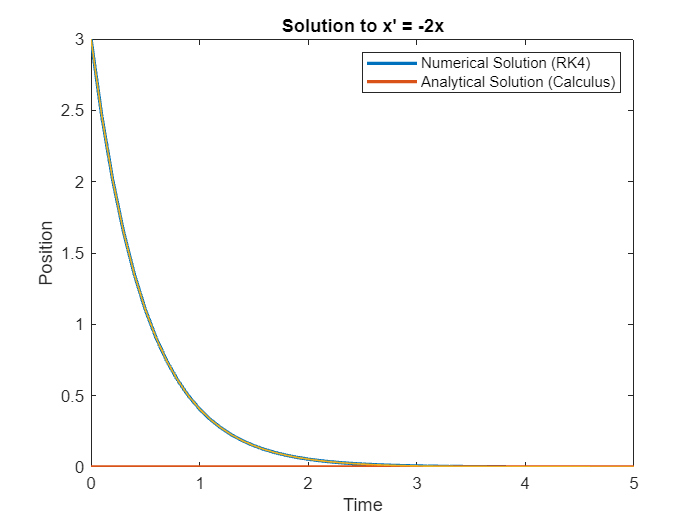

function [t, x] = rk4(f, x0, t0, tstop, dt)
    
    t = t0 : dt : tstop;
    x = zeros(length(t));

    x(1) = x0;

    for ii = 1:length(t)
        k1 = f(t(ii), x(ii));
        k2 = f(t(ii) + dt / 2, x(ii) + dt * k1 / 2);
        k3 = f(t(ii) + dt / 2, x(ii) + dt * k2 / 2);

        k4 = f(t(ii) + dt, x(ii) + dt * k3);

        x(ii+1) = x(ii) + (dt / 6) * (k1 + 2*k2 + 2*k3 + k4);
    end
end

[rk4_t, rk4_x] = rk4(f, x0, t0, tstop, dt);

figure
plot(rk4_t, rk4_x, 'LineWidth', 2)
xlabel("Time")
ylabel("Position")
title("Solution to x' = -2x")
hold on;
plot(t, f_actual(t), 'LineWidth', 1)
legend("Numerical Solution (RK4)", "Analytical Solution (Calculus)");
hold off;

#### Comparing Results

In most engineering applications, you will want to look at the differences between either two types of solutions or your approximate solution vs the data given. In either way, engineers love to call this types of calculations *"Deltas"* or *"Residuals"*. This probably stems back from the term residuals in Statistics when calculating Pearson's r coefficient for best fit.

In this case, we will develop a function called Plot_Residuals where we will take in two curves, compute their difference, and then display it on a graph. This will show us how effective our solution is. 

#### Code

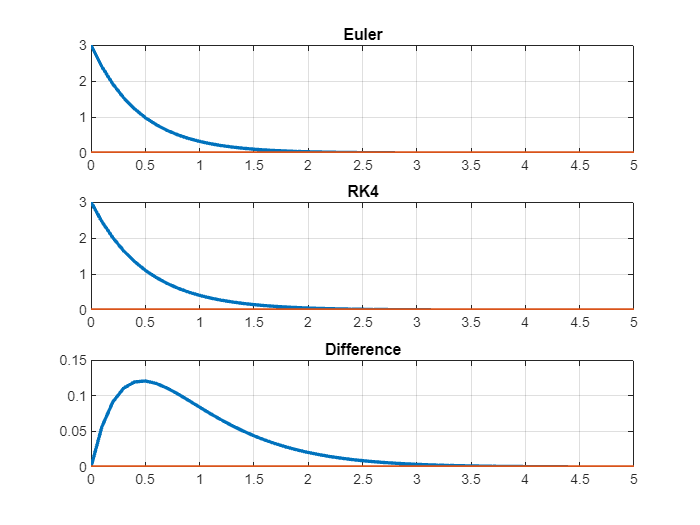

figure()

subplot(3,1,1)
plot(t, x, 'LineWidth', 2)

title("Euler")
grid on


subplot(3,1,2)
plot(rk4_t,rk4_x, 'LineWidth', 2)
title("RK4")
grid on

subplot(3,1,3)
plot(t, abs(rk4_x - x), 'lineWidth', 2)
title("Difference")
grid on;

## Introduction to PDEs

### Mathematical Background

#### Heat Equation

For this section, we are going to focus on the Partial Differential Equation


$$\frac{\partial U}{\partial t} = D \frac{\partial^2 U}{\partial x^2}$$


or commonly seen in a more compact notation


$$\partial_t U = D \partial_{xx} U$$


### Important Algorithm (Finite Difference Method)

#### Mathematical Formulation

Without derivation, the code for the update section of $U(t,x)$ is:


$$U_{i}^{n+1} = U_{i}^{n} + \frac{D \Delta t}{\Delta x^2} \left( U_{i+1}^n - 2 U_i^n + U_{i-1}^n\right)$$


For this problem we are going to set up the following boundary conditions:

$x \in (0,1)$, $u(0,x) = \sin(2 \pi x)$, $u(t,0) = u(t,1) = 0$.

We shall set $dt = 0.05$, $D = 0.5$, and $\Delta x = 0.1$. The reasoning for these values goes beyond the scope of the class and can be researched looking at stability methods for finite difference schemes. This is a very rich topic that deserves its own class. 

#### Code

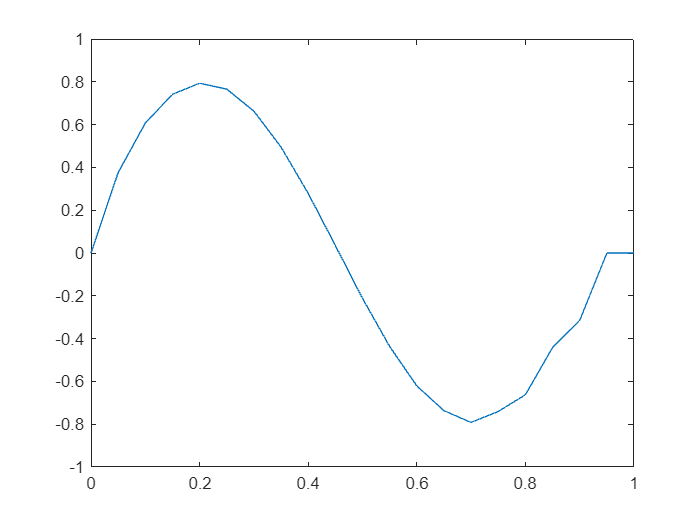

% Simulation Setup
dt = 0.001;
t = 0:dt:1;

dx = 0.05;
x = 0 : dx : 1;

D = 0.1;
a = D*dt/(dx^2);

% boundary conditions
U = zeros(length(t), length(x));
U(:,1) = 0;
U(:, end) = 0;
U(1, :) = sin(2*pi*x);

% solving loop:
for n = 1:length(t) - 1
    U(n+1, 2:end-2) = U(n, 2:end-2) + a*(U(n, 4:end) - 2*U(n, 2:end-2) + U(n, 1:end-3));
end

figure()
plot(x, U(25,:))
ylim([-1, 1])

## Exercises

1. Given the code for the Euler Method and RK4, code a very common middlepoint called the midpoint_1d solver:

The algorithm setup is the same as euler method but the math changes slightly:


$$k_1 = f(t_n, x_n)$$



$$x_{n+1} = x_n + dt \cdot f\left(t_n + \frac{dt}{2}, x_n + \frac{dt}{2}k_1\right)$$


Compare to Euler and RK4. (Comparisons are done through residuals calculations, see lecture at the end of the ODE section).

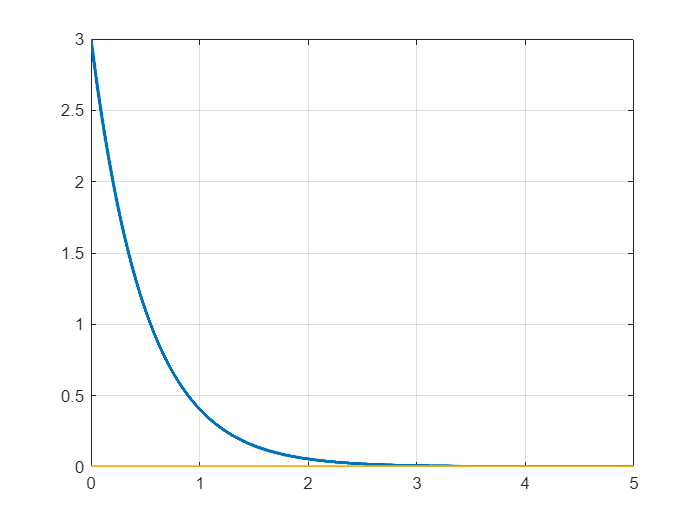

function [t, x] = midpoint_1d(f, x0, t0, tstop, dt)

    t = t0 : dt : tstop;
    x = zeros(length(t));


    x(1) = x0;
    
    for i = 1:length(t)
        k1 = f(t(i), t(i));
        x(i + 1) = x(i) + dt * f(t(i) + dt/2, x(i) + (dt/2)*k1);
    end
end

[midpoint_t, midpoint_x] = midpoint_1d(f, x0, t0, tstop, dt);

figure()
plot(midpoint_t, midpoint_x, 'LineWidth', 2)
grid on;